% デフォルトの線の幅を設定
set(0,'DefaultLineLineWidth',1);

% デフォルトのフォント設定
fontsize = 16; % フォントサイズ
fontname = 'Helvetica'; % 使用フォント
set(0,'defaultAxesFontSize',fontsize);
set(0,'defaultTextFontSize',fontsize);
set(0,'defaultAxesFontName',fontname);
set(0,'defaultTextFontName', fontname);


x, y軸の設定

n = 11; % n列目
m = 13; % m列目
N = [n, m]

N =     11    13


c = 1

c = 1

%     data(:, 5) =(data(:, 1) - valueToSubtractFx) .* 100; % Fxの計算
%     data(:, 6) = (data(:, 2) - valueToSubtractFy)  .* 100; % Fyの計算
%     data(:, 7) = (data(:, 3) - valueToSubtractX) .* 100 ./ 50; % epsilonXの計算
%     data(:, 8) = (valueToSubtractY - data(:, 4)) .* 100 ./ 50; % epsilonYの計算
%     data(:, 9) = data(:, 7) .* 0.853; % 真のepsilonXの計算
%     data(:, 10) = data(:, 8) .* 0.853; % 真のepsilonYの計算
%     data(:, 11) = data(:, 9) + 1; % lambdaXの計算
%     data(:, 12) = data(:, 10) + 1; % lambdaYの計算
%     data(:, 13) = data(:, 5) ./ 31.25; % sigmaXの計算
%     data(:, 14) = data(:, 6) ./ 31.25; % sigmaYの計算
%     data(1, 15) = 0; % deltaXの初期値
%     data(1, 16) = 0; % deltaYの初期値
%     data(2:end, 15) = diff(data(:, 11)); % deltaXの計算
%     data(2:end, 16) = diff(data(:, 12)); % deltaYの計算
%     data(:, 17) = data(:, 13) .* data(:, 15); % wiXの計算
%     data(:, 18) = data(:, 14) .* data(:, 16); % wiYの計算
%     data(:, 19) = data(:, 11) .^ 2 + data(:, 12) .^ 2 + (1 ./ (data(:, 11) .* data(:, 12)))  .^ 2; % I1の計算
%     data(:, 20) = (data(:, 11) .* data(:, 12)) .^2 + (data(:, 12) .* (1 ./ (data(:, 11) .* data(:, 12)))) .^2 + ((1 ./ (data(:, 11) .* data(:, 12))) .* data(:, 11)) .^2; % I2の計算
%     data(:, 21) = cumsum(data(:, 17)) + cumsum(data(:, 18)) % Wの計算

virginLoading, reLoading, unLoadingのプロット(uniaxial)

% CSVファイルが保存されているフォルダのパスを指定
folderPath = 'DataPath';

% フォルダ内のCSVファイルのリストを取得
fileList = dir(fullfile(folderPath, '*.csv'))

% ファイル数を取得

fileList = フィールドをもつ 37×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


fileList = フィールドをもつ 30×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


numFiles = 30

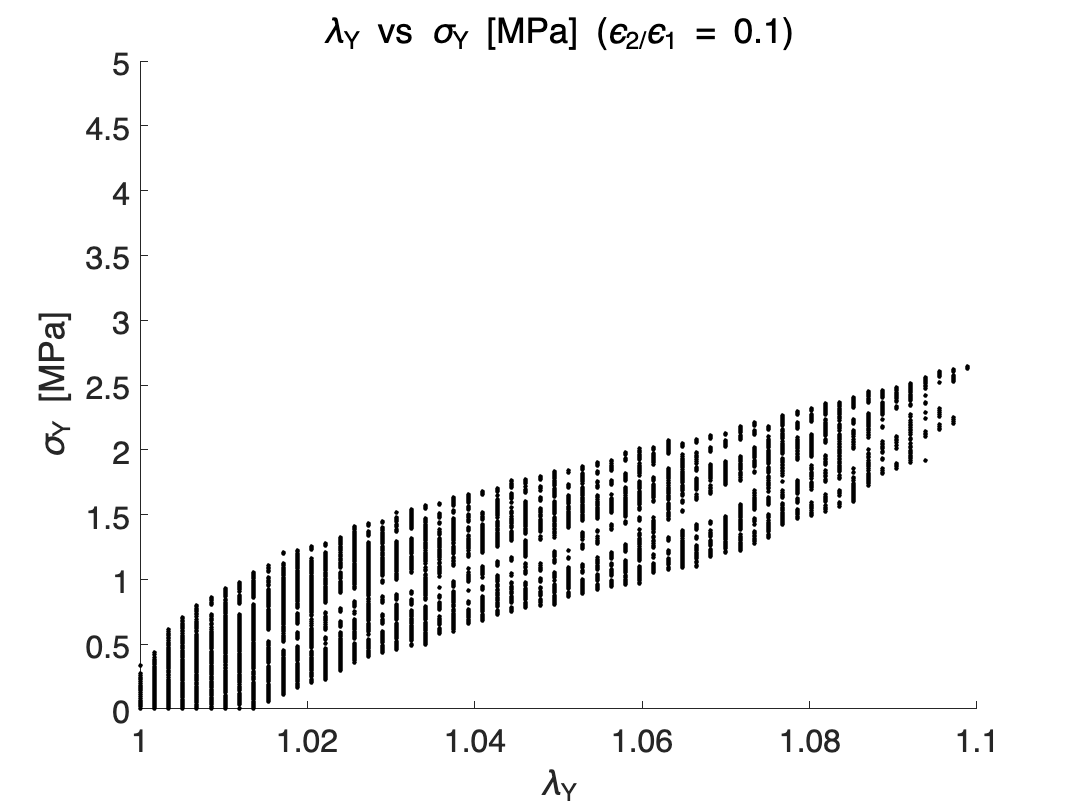

fileList = フィールドをもつ 31×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


fileList = フィールドをもつ 32×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


numFiles = 32

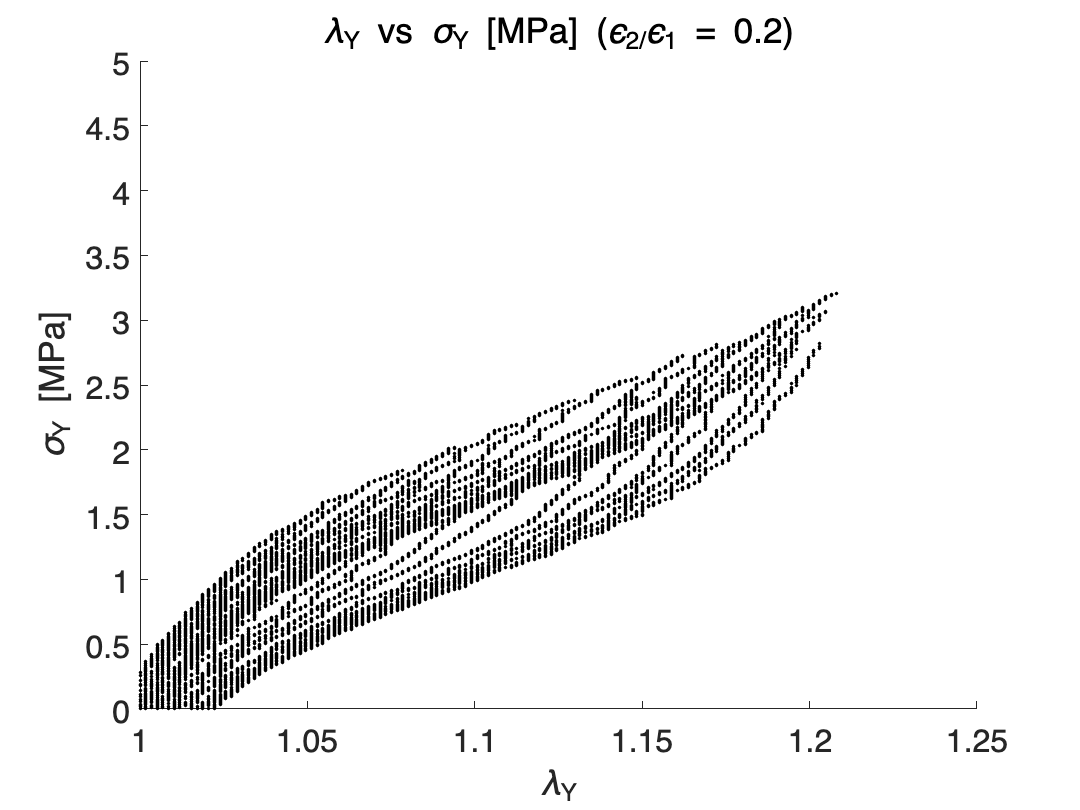

fileList = フィールドをもつ 32×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


fileList = フィールドをもつ 35×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


numFiles = 35

fileList = フィールドをもつ 35×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


fileList = フィールドをもつ 38×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


numFiles = 38

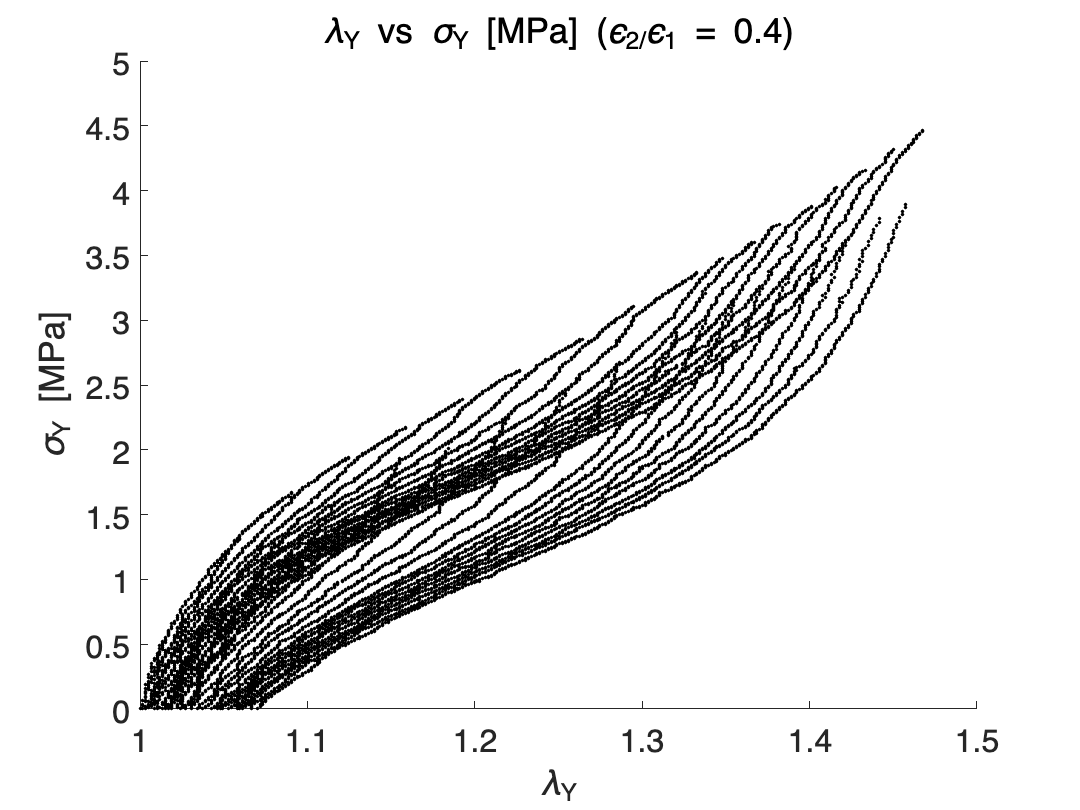

fileList = フィールドをもつ 39×1 の struct 配列:
    name
    folder
    date
    bytes
    isdir
    datenum


%numFiles = numel(fileList)

% 新しい図を作成
figure;
% ax1 = axes('Position',[0.1 0.1 0.7 0.7]);
% ax2 = axes('Position',[0.65 0.65 0.28 0.28]);

% yyaxis left
hold on

% ループを使用して各CSVファイルについてプロットを行う

for i = [2 4 6 8 10 12 14 16 18 20 22 24 26 28 30 32 34 36]
    % ファイルのフルパスを取得
    filePath = fullfile(folderPath, fileList(i).name);
    
    % CSVファイルを読み込む
    data = readmatrix(filePath);

    % n列目をx軸、m列目をy軸としてプロット
    xData = data(:, 11);
    yData = data(:, 13);
    %pixel_values = data(:, 28);   % データを画素値として取得

    % プロット
    scatter(xData, yData, c, 'filled', "MarkerFaceColor", "#0072BD", "MarkerEdgeColor","#0072BD");
    %h = colorbar;
   
end

hold off

%xlim([1, 2.2])
ylim([0, 4])
% 軸のラベルを設定（必要に応じて）
    xlabel('\lambda_X');
    ylabel('\sigma [MPa]');


% yyaxis right
hold on

% ループを使用して各CSVファイルについてプロットを行う

% for i = [2 4 6 8 10 14 18 21 23 25 27 29 33 37]
%     % ファイルのフルパスを取得
%     filePath = fullfile(folderPath, fileList(i).name);
% 
%     % CSVファイルを読み込む
%     data = readmatrix(filePath);
% 
%     % n列目をx軸、m列目をy軸としてプロット
%     xData = data(:, 11);
%     yData = data(:, 14);
%     %pixel_values = data(:, 28);   % データを画素値として取得
% 
%     % プロット
%     scatter(xData, yData, c, 'filled', "MarkerEdgeColor", "#D95319", "MarkerFaceColor", "#D95319");
%     %h = colorbar;
% 
% end

hold off


%xlim([1, 1.1])
%ylim([0, 6])
% 軸のラベルを設定（必要に応じて）
    % xlabel('\lambda_X');
    % ylabel('\sigma_Y [MPa]');
title('\lambda_X vs \sigma_X [MPa], \sigma_Y [MPa](Uniaxial)');
% フィギュアを保存（任意）
    %saveas(gcf, 'scatterOfLambdaVsSigmax_U.png');